### 读数据

open('Aluminum_DC_real.fig')
hl = get(gca,'Children');    % 获取坐标轴的子对象：Line对象
xdata = get(hl,'XData');
ydata = get(hl,'YData');

### 频散曲线

fig1 = figure();
plot(xdata{1},ydata{1},'.r','MarkerSize',4)
hold on 
plot(xdata{2},ydata{2},'.b','MarkerSize',4)
hold off

### 交点

	输入：w_sca（频率）

	输出：交点横坐标（对应波数）

yint = w_sca;
XInter_Sym =  find_intersection(xdata{1},ydata{1},yint,fig1)

XInter_Sym =    1.019495441423492   2.699724044632164


XInter_aym = find_intersection(xdata{2},ydata{2},yint,fig1)

XInter_aym =    1.791918460890084


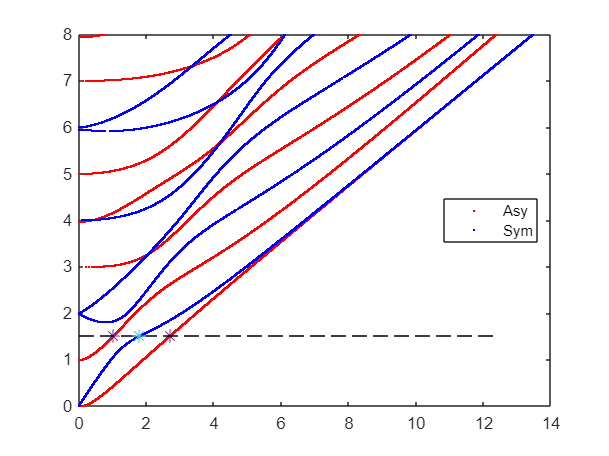

legend('Asy','Sym','location','east')

function XIntersectionPoint = find_intersection(x,y,yLine,fig)
%% 寻找交点，输出交点横坐标 XIntersectionPoint

figure(fig)

%% 辅助虚线
hold on
xdata_dash = linspace(x(1),x(end),100);
ydata_dash = yLine*ones(size(xdata_dash));
plot(xdata_dash,ydata_dash,'--k')
hold off

%% 交点
hold on
ydata_New = yLine*ones(size(yLine));
dY = ydata_New./(y+eps);	
dX = sort(x(dY>1-1e-3 & dY<1+1e-3));

% 区分交点
idx_IntersectionPoint = diff(dX)>1e-2;
idx_IntersectionPoint = logical([0 idx_IntersectionPoint]);
XIntersectionPoint = [dX(1) dX(idx_IntersectionPoint)];
YIntersectionPoint = yLine*ones(size(XIntersectionPoint));
plot(XIntersectionPoint,YIntersectionPoint,'*','MarkerSize',8)
hold off



end